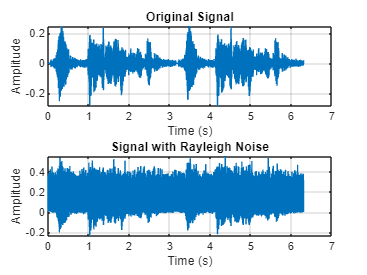

% Read the audio file
[originalSignal, fs] = audioread('audio.wav');

% If stereo, convert to mono for simplicity
if size(originalSignal, 2) > 1
    originalSignal = mean(originalSignal, 2);
end

% Parameters for Rayleigh noise
sigma = 0.1; % Adjust this value to control noise intensity
noiseLength = length(originalSignal);

% Generate Rayleigh noise
noise = sigma * sqrt(-2 * log(1 - rand(noiseLength, 1)));

% Add noise to signal
noisySignal = originalSignal + noise;

% Play original and noisy signals
sound(originalSignal, fs);
pause(length(originalSignal)/fs + 1); % Wait for original to finish
sound(noisySignal, fs);

% Plot original vs noisy signals
t = (0:length(originalSignal)-1)/fs;
figure;
subplot(2,1,1);
plot(t, originalSignal);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(t, noisySignal);
title('Signal with Rayleigh Noise');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;


% Noise Removal using Spectral Subtraction
% Convert signals to frequency domain
windowLength = 1024;
overlap = windowLength/2;
window = hamming(windowLength);

% STFT of noisy signal
[S, f, t] = spectrogram(noisySignal, window, overlap, windowLength, fs);

% Estimate noise spectrum from a noise-only segment
% Assuming first few frames are noise-only (adjust as needed)
noiseFrames = 5;
noiseSpectrum = mean(abs(S(:, 1:noiseFrames)), 2);

% Spectral Subtraction
cleanSpectrum = abs(S) - noiseSpectrum;
cleanSpectrum = max(cleanSpectrum, 0); % Half-wave rectification
cleanPhase = angle(S);

% Reconstruct complex spectrum
cleanS = cleanSpectrum .* exp(1i * cleanPhase);

% Inverse STFT to get clean signal
cleanSignal = istft(cleanS, window, overlap, windowLength);
cleanSignal = cleanSignal(1:length(originalSignal)); % Match original length

Index exceeds the number of array elements. Index must not exceed 302080.


% Normalize cleaned signal
cleanSignal = cleanSignal / max(abs(cleanSignal));

% Play cleaned signal
pause(1);
sound(cleanSignal, fs);

% Plot cleaned signal
figure;
plot(t, cleanSignal);
title('Cleaned Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Calculate and display SNR improvements
originalSNR = snr(originalSignal, noise);
cleanedSNR = snr(originalSignal, originalSignal - cleanSignal);

fprintf('Original SNR: %.2f dB\n', originalSNR);
fprintf('Cleaned SNR: %.2f dB\n', cleanedSNR);

% Optional: Save the results
audiowrite('noisy_signal.wav', noisySignal, fs);
audiowrite('cleaned_signal.wav', cleanSignal, fs);

% Helper function for ISTFT (Inverse Short-Time Fourier Transform)

function x = istft(S, window, overlap, nfft)
    % Initialize output signal
    cols = size(S, 2);
    samples = (cols-1)*overlap + nfft;
    x = zeros(samples, 1);
    w = zeros(samples, 1);
    
    % Reconstruction
    for i = 1:cols
        start = (i-1)*overlap + 1;
        spec = S(:,i);
        
        % Inverse FFT
        frame = real(ifft(spec, nfft));
        frame = frame(1:length(window)) .* window;
        
        x(start:start+length(window)-1) = x(start:start+length(window)-1) + frame;
        w(start:start+length(window)-1) = w(start:start+length(window)-1) + window;
    end
    
    % Normalize by window overlap
    x = x ./ w;
    
    % Remove any NaN values
    x(isnan(x)) = 0;
end